% Question 3: Hamiltonian Markov Chain Monte Carlo

% Target distribution: multivariate gaussian, call i P(x)
mu = [0 0]; % mean of P(x)
rho = 0.998; 
sigma = [1 rho; rho 1]; % covariance matrix of P(x)
% ... so dimension D = 2

%target dist: 
P = @(X) mvnpdf(X, mu, sigma); 

% Plot the target distribution
x1 = linspace(-1, 1);   % 1 x 100
x2 = x1;
[xx1 xx2] = meshgrid(x1, x2); 
% size(xx1) = 100 x 100

% note: the : operator stacks the cols in each xx1
% so that the end resul of xx1(:) is an (n*c) x 1 array
xValues = [xx1(:) xx2(:)] % size = 1000 x 2

xValues =   -1.000000000000000  -1.000000000000000
  -1.000000000000000  -0.979797979797980
  -1.000000000000000  -0.959595959595960
  -1.000000000000000  -0.939393939393939
  -1.000000000000000  -0.919191919191919
  -1.000000000000000  -0.898989898989899
  -1.000000000000000  -0.878787878787879
  -1.000000000000000  -0.858585858585859
  -1.000000000000000  -0.838383838383838
  -1.000000000000000  -0.818181818181818
  -1.000000000000000  -0.797979797979798
  -1.000000000000000  -0.777777777777778
  -1.000000000000000  -0.757575757575758
  -1.000000000000000  -0.737373737373737
  -1.000000000000000  -0.717171717171717
  -1.000000000000000  -0.696969696969697
  -1.000000000000000  -0.676767676767677
  -1.000000000000000  -0.656565656565657
  -1.000000000000000  -0.636363636363636
  -1.000000000000000  -0.616161616161616
  -1.000000000000000  -0.595959595959596
  -1.000000000000000  -0.575757575757576
  -1.000000000000000  -0.555555555555556
  -1.000000000000000  -0.535353535353535
  -1.0

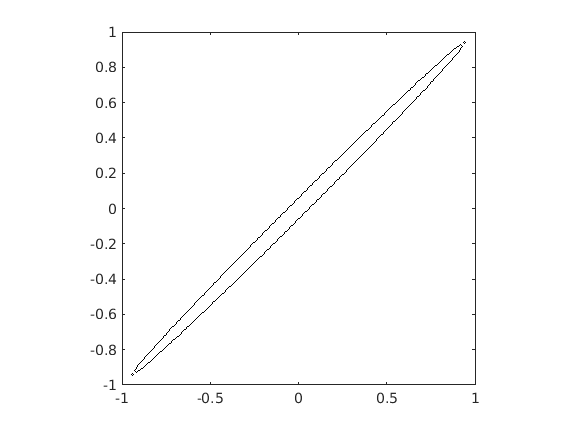

%Pcontour = P(xValues) % size = 1000 x 1
Pcontour = reshape(P(xValues), 100, 100);
% need to reshape to be same size as the xx1, xx2 in 
% the contour args

figure(1); clf
contour(xx1, xx2, Pcontour, [1.6, 3], 'k');
axis square

% Hamiltonian MCMC algorithm
% Define energy function E
A = inv(sigma);
findE = @(X) 0.5*X*A *A'; % energy E, is negative log of P
findGradE = @(X) A* X'; % gradient of E
findK = @(P) P * P' / 2;

[X_sto, X_trm, na, T] = hamiltonianMonteCarlo(findE, findGradE, findK)

X_sto =   -0.900000000000000  -0.700000000000000
  -0.836949109266665  -0.785277562344318
  -0.740588595130530  -0.901834934938770
  -0.743979501126003  -0.916585802904530
  -0.854210453525829  -0.822418840051485
  -0.943522705253453  -0.747072693369168
  -0.908996019749456  -0.793450124310586
  -0.801188055662194  -0.910978645967327
  -0.760928035151758  -0.958816873319477
  -0.843272622011867  -0.881898660332524
  -0.948679171459559  -0.779759862032332
  -0.947429796763550  -0.782114276372473
  -0.841776174730315  -0.886708843864234
  -0.763124086384637  -0.962139108626153
  -0.807777018074159  -0.912105615621376
  -0.916559320581984  -0.795790746500881
  -0.948789974207110  -0.753884946099065
  -0.858139748202455  -0.832729551202525
  -0.750550297909552  -0.926397678267649
  -0.751816318713722  -0.909112050982225
  -0.850353052835296  -0.792477471678577
  -0.923830242906194  -0.792547787372115
  -0.864535141024586  -0.966073299374026
  -0.867556112560578  -1.074992186856738
  -0.999

X_trm =   -0.900000000000000  -0.700000000000000
  -0.900000000000000  -0.700000000000000
  -0.900000000000000  -0.700000000000000
  -0.900000000000000  -0.700000000000000


na =      0


T =      3


%%% Hamiltonian algorithm %%%
% Initialize values
find_E = findE

find_E = function_handle with value:
    @(X)0.5*X*A*A'


find_gradE = findGradE

find_gradE = function_handle with value:
    @(X)A*X'


T = 3;
Tau = 20;
epsilon = 0.05;
X_stored_sub = zeros(Tau, 2);
X_stored = zeros(1, 2);
X_term = zeros(T+1, 2);
accepted = 0;
X = [-0.9 -0.7];
X_stored(1,:) = X;
X_term = X;
E = find_E(X);
gradE = find_gradE(X);
% Loop T times
for i = 1:T
    P = randn(size(X));
    H = P*P'/2 + E;
    X_new = X;
    gradE_new = gradE;
    % Take Tau "leapfrog" steps
    for j = 1:Tau
        P = P - epsilon*gradE_new'/2;
        X_new = X_new + epsilon*P;
        gradE_new = find_gradE(X_new);
        P = P - epsilon*gradE_new'/2;
        X_stored_sub(j,:) = X_new;
    end
    % Update H
    E_new = find_E(X_new);
    H_new = P*P'/2 + E_new;
    dH = H_new - H;
    % Decide whether to accept
    if dH < 0
        accept = 1;
    elseif rand() < exp(-dH)
        accept = 1;
    else
        accept = 0;
    end
    if accept
        X = X_new; E = E_new; gradE = gradE_new;
    end
    accepted = accepted + accept;
    X_stored = [X_stored; X_stored_sub];
    X_term(i+1,:) = X;
end

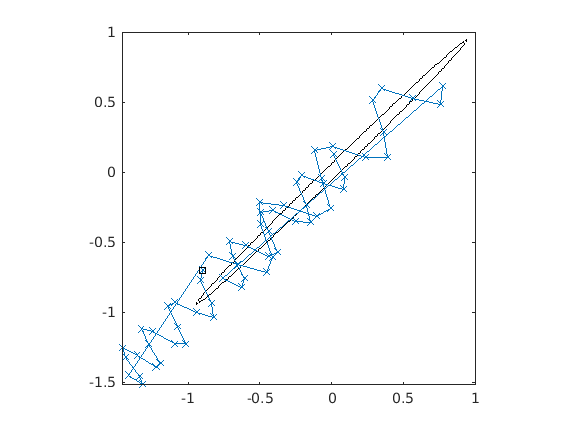


% Plot samples

figure(1); hold on; 
plot(X_stored(:, 1), X_stored(:,2), '-x')
hold on; 
plot(X_term(:, 1), X_term(:, 2), 'ksq')


acceptanceRate = na/T;
